# Experiment 2.2 MODIFIED

## Name: Test Test

## Objectives

To learn to use MATLAB and the Symbolic Math Toolbox to

- Find Laplace transforms for time functions

- Find time functions from Laplace transforms

- Create LTI transfer functions from symbolic transfer functions.

- Perform solutions of symbolic simultaneous equations.

### Minimum Required Software Packages

MATLAB, the Symbolic Math Toolbox, and the Control System Toolbox.

## Prelab

### Problem 1

*Using a hand calculation, find the Laplace transform of: *$f(t) = 0.0075 - 0.00034 e^{-2.5t}\cos(22t) + 0.087 e^{-2.5t}\sin(22t) - 0.0072 e^{-8t}$

Answer: 


$$\frac{0.0075}{s} - 0.00034(\frac{s+2.5}{(s+2.5)^2 + 22^2)}) + 0.087(\frac{22}{(s+2.5)^2 + 22^2}) - 0.0072(\frac{1}{s+8})$$


### Problem 2

*Using a hand calculation, find the inverse Laplace transform of: *$F(s) = \frac{2(s+3)(s+5)(s+7)}{s(s+8)(s^2 + 10s + 100)}$

Answer:

### Problem 3

*Calculate by hand the transfer function of the following systems. Then solve for the rise time, poles, and the steady-state final value for the step-response.*

#### *3.a.*

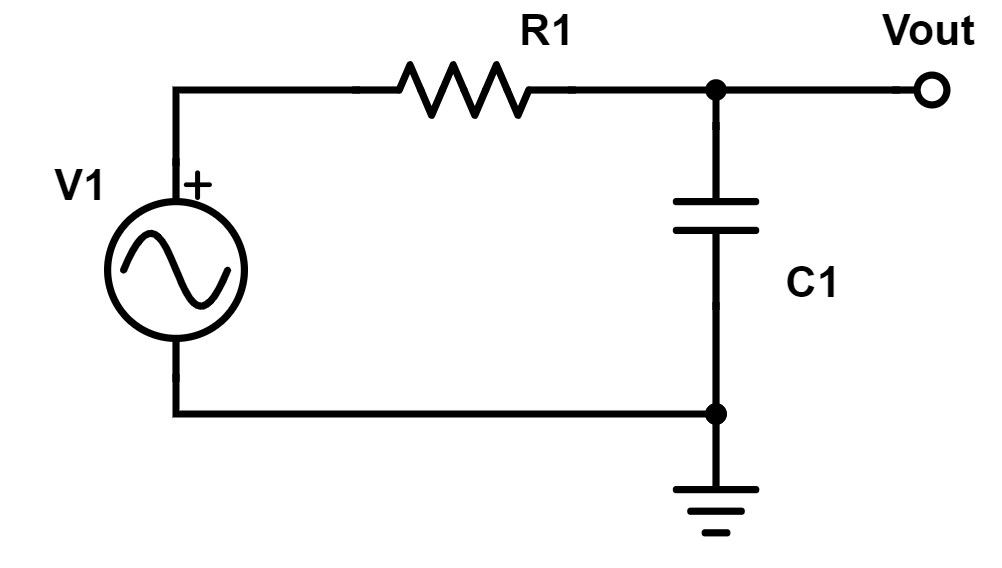

Answer:

**Poles:**

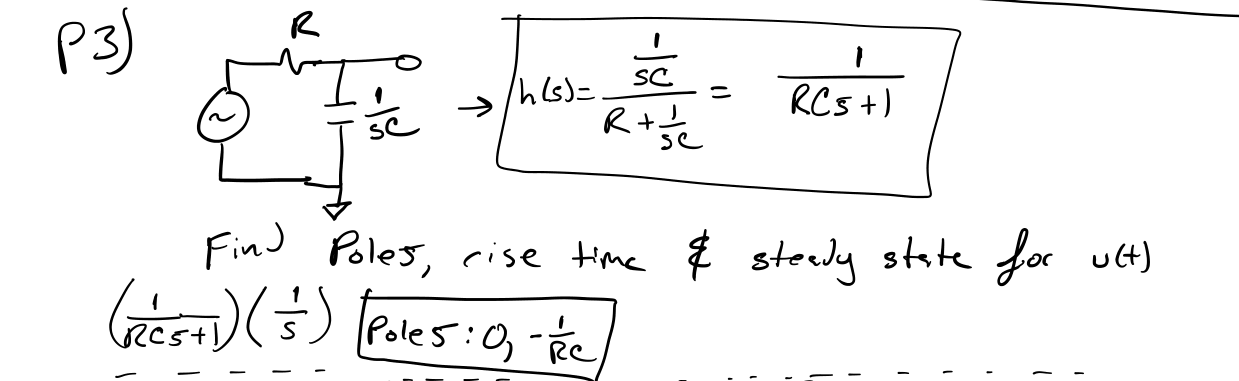

**Steady State Value**

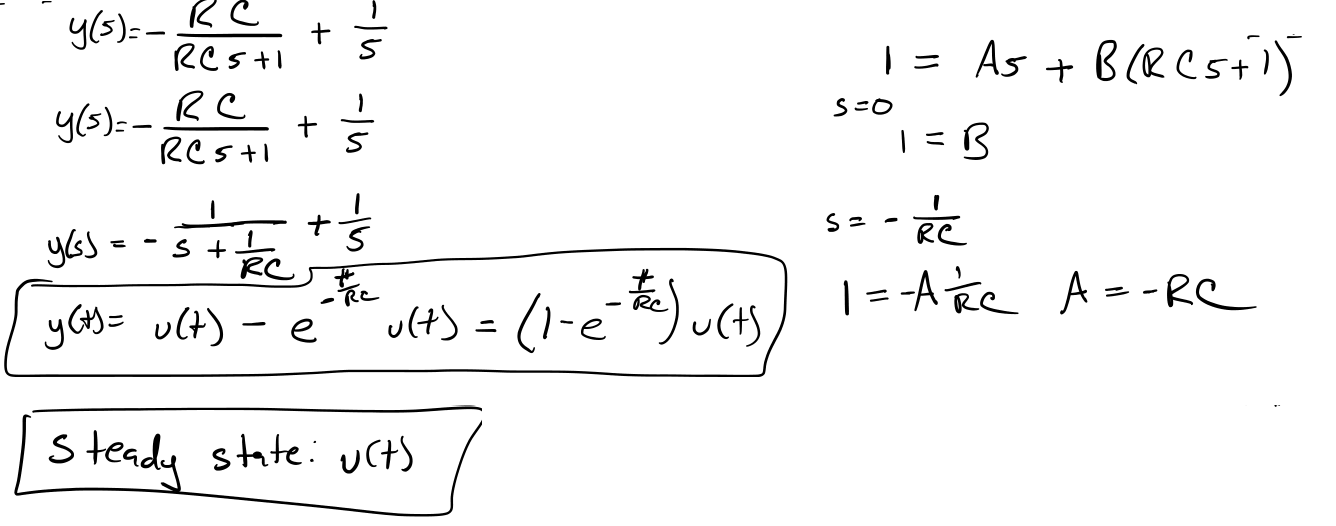

**Rise Time**

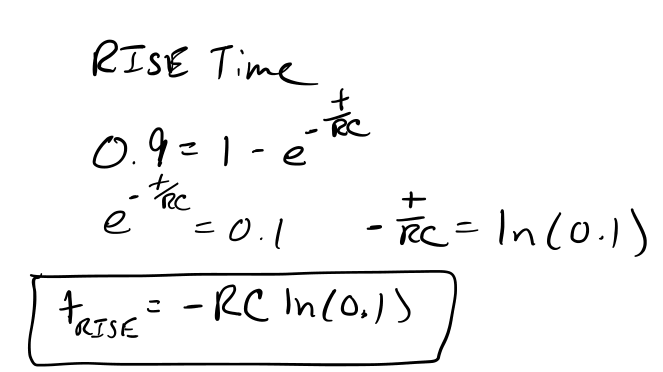

#### 3.b.

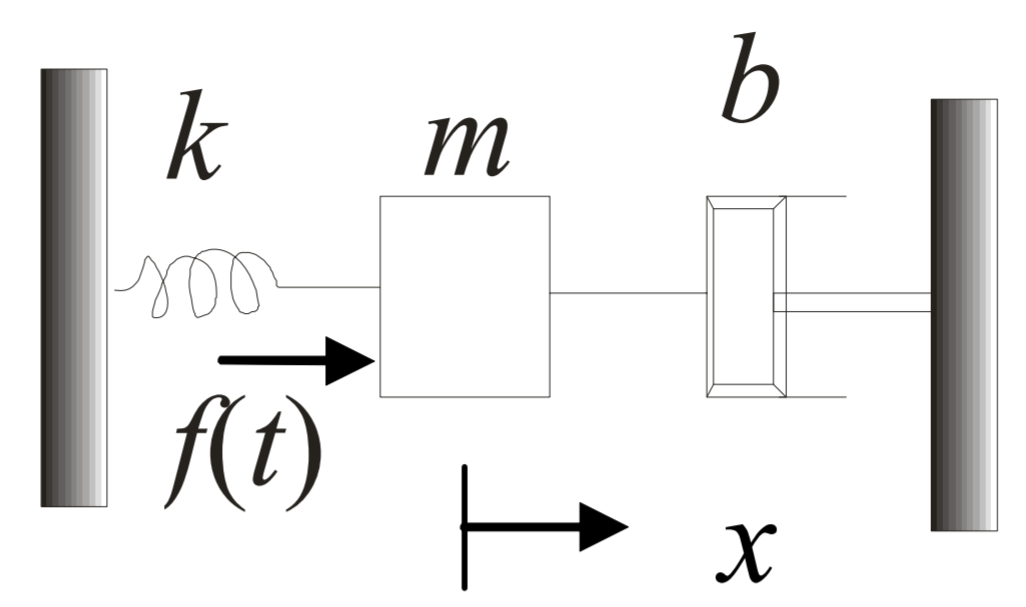

For this problem, **ONLY SOLVE FOR THE TRANSFER FUNCTION.** You will be looking for the displacement caused by the force.

Answer:

#### 3.c.

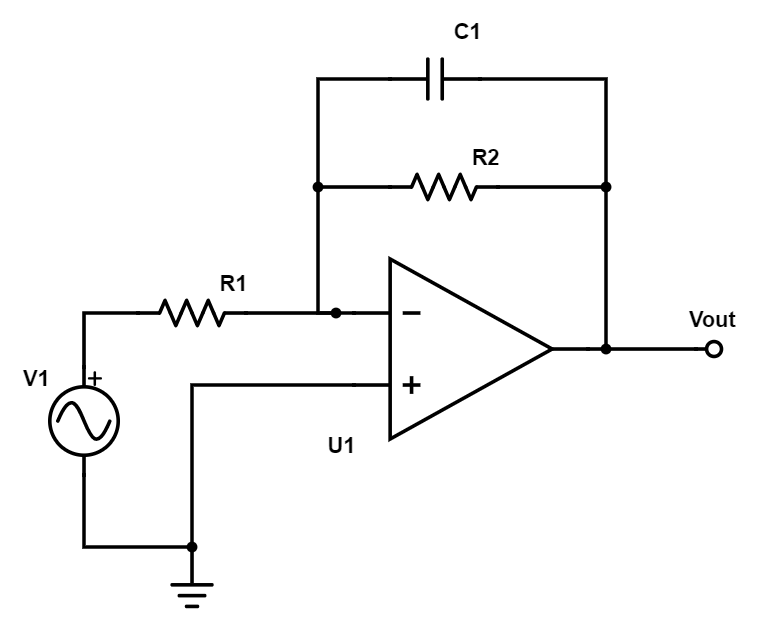

Answer:

## Lab

### Problem 1

*Use MATLAB and the Symbolic Math Toolbox to*

#### 1.a.

*Using a hand calculation, find the Laplace transform of: *$f(t) = 0.0075 - 0.00034 e^{-2.5t}\cos(22t) + 0.087 e^{-2.5t}\sin(22t) - 0.0072 e^{-8t}$

*Generate symbolically the time function f(t) shown in Prelab Problem 1*

syms t;
f = 0.0075 - 0.00034*exp(-2.5*t)*cos(22*t) + 0.087*exp(-2.5)*sin(22*t) - 0.0072*exp(-8*t)

$$f = \frac{8233467730363123\,\sin\left(22\,t\right)}{1152921504606846976}-\frac{9\,{\mathrm{e}}^{-8\,t}}{1250}-\frac{17\,\cos\left(22\,t\right)\,{\mathrm{e}}^{-\frac{5\,t}{2}}}{50000}+\frac{3}{400}$$

#### 1.b.

*Generate symbolically F(s) shown in Prelab Problem 2. Obtain your result symbolically in both factored and polynomial form*


$$F(s) = \frac{2(s+3)(s+5)(s+7)}{s(s+8)(s^2 + 10s + 100)}$$


syms s;
disp("Factored");

Factored


F = (2*(s+3)*(s+5)*(s+7))/((s)*(s+8)*(s^2 + 10*s + 100))

$$F = \frac{\left(2\,s+6\right)\,\left(s+5\right)\,\left(s+7\right)}{s\,\left(s+8\right)\,\left(s^{2}+10\,s+100\right)}$$

factor(F)

$$ans = \left(\begin{array}{ccccccc} 2 & s+3 & s+5 & s+7 & \frac{1}{s} & \frac{1}{s+8} & \frac{1}{s^{2}+10\,s+100} \end{array}\right)$$

disp("Polynominal");

Polynominal


[n,d] = numden(F);
expand(n)/expand(d)

$$ans = \frac{2\,s^{3}+30\,s^{2}+142\,s+210}{s^{4}+18\,s^{3}+180\,s^{2}+800\,s}$$

#### 1.c.

*Find the Laplace Transform of f(t) shown in Prelab Problem 1*

syms t;
f = 0.0075 - 0.00034*exp(-2.5*t)*cos(22*t) + 0.087*exp(-2.5)*sin(22*t) - 0.0072*exp(-8*t)

$$f = \frac{8233467730363123\,\sin\left(22\,t\right)}{1152921504606846976}-\frac{9\,{\mathrm{e}}^{-8\,t}}{1250}-\frac{17\,\cos\left(22\,t\right)\,{\mathrm{e}}^{-\frac{5\,t}{2}}}{50000}+\frac{3}{400}$$

F_poly = laplace(f)

$$F\_poly = \frac{90568145033994353}{576460752303423488\,\left(s^{2}+484\right)}-\frac{9}{1250\,\left(s+8\right)}-\frac{17\,\left(s+\frac{5}{2}\right)}{50000\,\left({\left(s+\frac{5}{2}\right)}^{2}+484\right)}+\frac{3}{400\,s}$$

#### 1.d.

*Find the inverse Laplace Transform of F(s) shown in Prelab Problem 2*


$$F(s) = \frac{2(s+3)(s+5)(s+7)}{s(s+8)(s^2 + 10s + 100)}$$


F = ( 2*(s+3)*(s+5)*(s+7) ) / ( (s)*(s+8)*(s^2+10*s+100) );
ilaplace(F)

$$ans = \frac{5\,{\mathrm{e}}^{-8\,t}}{112}+\frac{237\,{\mathrm{e}}^{-5\,t}\,\left(\cos\left(5\,\sqrt{3}\,t\right)+\frac{\sqrt{3}\,\sin\left(5\,\sqrt{3}\,t\right)}{9}\right)}{140}+\frac{21}{80}$$

### Problem 2

*Using MATLAB, find the values for the characteristics requested in Prelab Problem 3.a. given *$R_1 = 1k\Omega, C_1 = 1\mu F$. *Using only MATLAB (no Simulink) find and plot the step response of the system.*

*Calculate by hand the transfer function of the following systems. Then solve for the rise time, poles, and the steady-state final value for the step-response.*

syms s;

R = 1000;
C = 1*10^(-6);

sys = 1/(R*C*s + 1);
X = 1/s;
y = ilaplace(sys*X);

[n,d] = numden(sys);
sys_tf = tf(sym2poly(n), sym2poly(d));
unitStep = tf([1], [1 0]);
Y_tf = sys_tf*unitStep;

[u,v] = step(sys_tf);

disp("Rise Time");

Rise Time


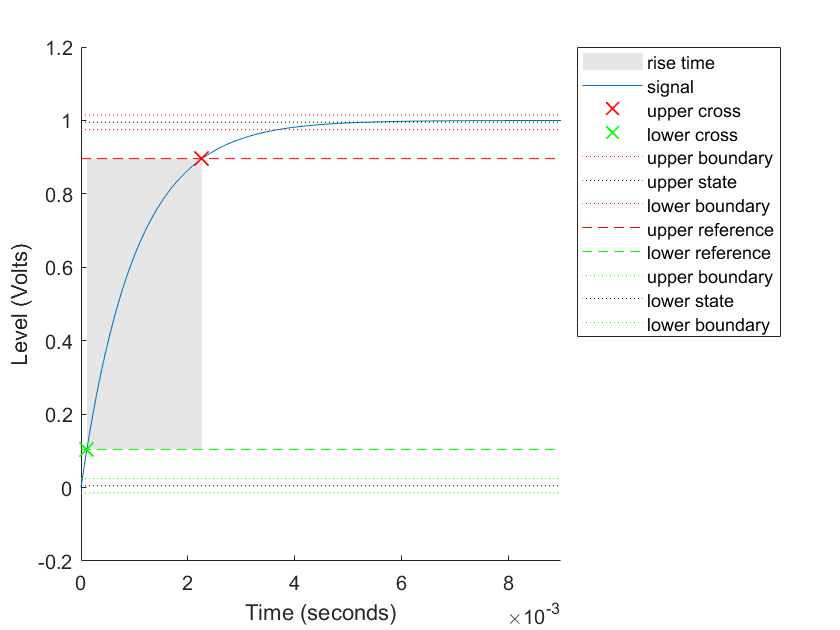

ans = 0.0022

risetime(u,v)


disp("Poles")

Poles


pole(Y_tf)

ans =            0
       -1000



disp("Steady State Value");

Steady State Value


limit(y, t, inf)

$$ans = 1$$

### Problem 4

#### 4.a.

*Using MATLAB, find the charcteristics requested in Prelab Problem 3.b. given *$k=2$ $b=20$, $m=2$. Plot the step response of the system and find the rise time and settling time.

For this problem, **ONLY SOLVE FOR THE TRANSFER FUNCTION.** You will be looking for the displacement caused by the force.

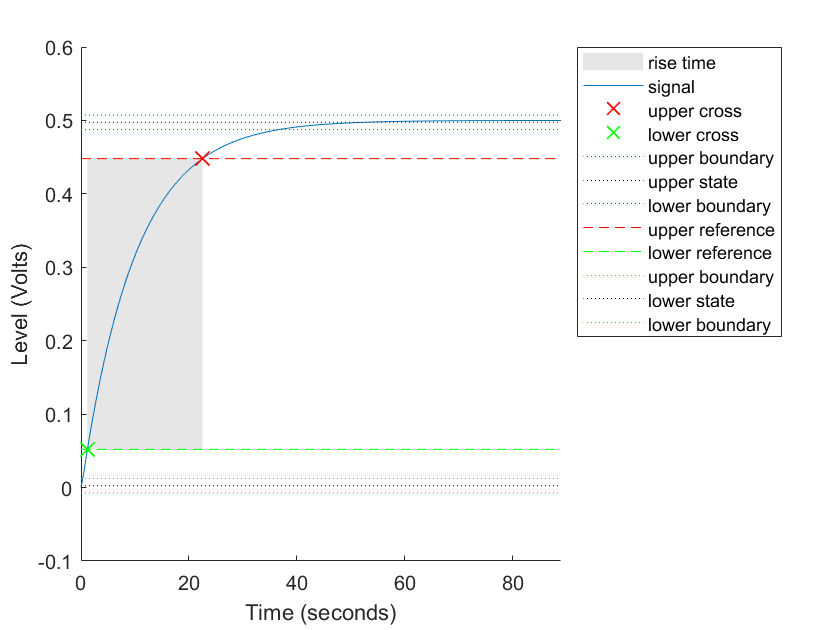

k = 2;
b = 20;
m = 2;
s = tf("s");
H = (1/(m*s^2 + b*s + k));
[u,v] = step(H);
risetime(u,v);

stepinfo(H)

ans = struct with fields:
        RiseTime: 21.7495
    SettlingTime: 38.8281
     SettlingMin: 0.4518
     SettlingMax: 0.5000
       Overshoot: 0
      Undershoot: 0
            Peak: 0.5000
        PeakTime: 104.3931


% syms s t
% k = 2;
% b = 20;
% m = 2;
% 
% Y = (1/(m*s^2 + b*s + k))*(1/s);
% disp("Step Response");
% y = ilaplace(Y,t)
% 
% %Plotting Step Response
% time = 0:0.1:80;
% plot(time, subs(y,time))
% title("Step Response of System")
% xlabel("Time (s)");
% ylabel("Force (N)");
% 
% %Solving for Rise time
% disp("Rise Time")
% eqn = (1/2)*0.90 == y;
% rise_time = vpasolve(eqn,t)
% 
% %Solving for Settling time
% disp("Settling Time")
% eqn = (1/2)*0.98 == y;
% settling_time = vpasolve(eqn,t)

#### 4.b.

*Using sliders in the live script, find the value for *$b$ *where it stops acting like a first order system.*

% Insert your code here
m = 2

m = 2

b = 3

b = 3

k = 2

k = 2

G = tf([1], [m, b, k])


G =
 
         1
  ---------------
  2 s^2 + 3 s + 2
 
Continuous-time transfer function.



pole(G*tf([1],[1,0]))

ans =    0.0000 + 0.0000i
  -0.7500 + 0.6614i
  -0.7500 - 0.6614i


[u,v] = step(G)

u =          0
    0.0009
    0.0035
    0.0077
    0.0133
    0.0202
    0.0281
    0.0371
    0.0470
    0.0576


v =          0
    0.0614
    0.1228
    0.1842
    0.2456
    0.3070
    0.3684
    0.4298
    0.4912
    0.5526


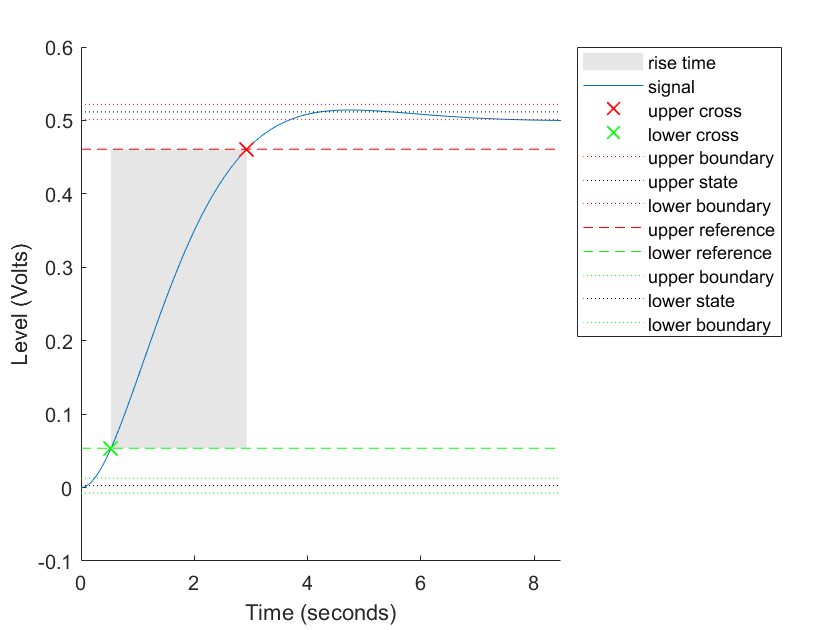

ans = 2.3959

risetime(u,v)

stepinfo(G)

ans = struct with fields:
        RiseTime: 2.2884
    SettlingTime: 5.7426
     SettlingMin: 0.4524
     SettlingMax: 0.5142
       Overshoot: 2.8369
      Undershoot: 0
            Peak: 0.5142
        PeakTime: 4.7280


### Problem 5

*For Prelab 3.c. find the rise-time for the circuit with the values of *$R_1 = 1k\Omega , R_2 = 1k\Omega, C_1 = 1\mu F$*. Using sliders and your transfer function from the Prelab, determine what happens to the step response and the rise time as you change *$R_1$ *and *$R_2$.

clc;
clear all;
syms t s;
R_1 = 8000

R_1 = 8000

R_2 = 3500

R_2 = 3500

c = 1*10^(-6)

c = 1.0000e-06

H_top = sym(-(R_2))

$$H\_top = -3500$$

H_bot = sym(c*R_1*R_2*s+R_1)

$$H\_bot = 28\,s+8000$$

H = tf(sym2poly(H_top), sym2poly(H_bot))


H =
 
     -3500
  -----------
  28 s + 8000
 
Continuous-time transfer function.



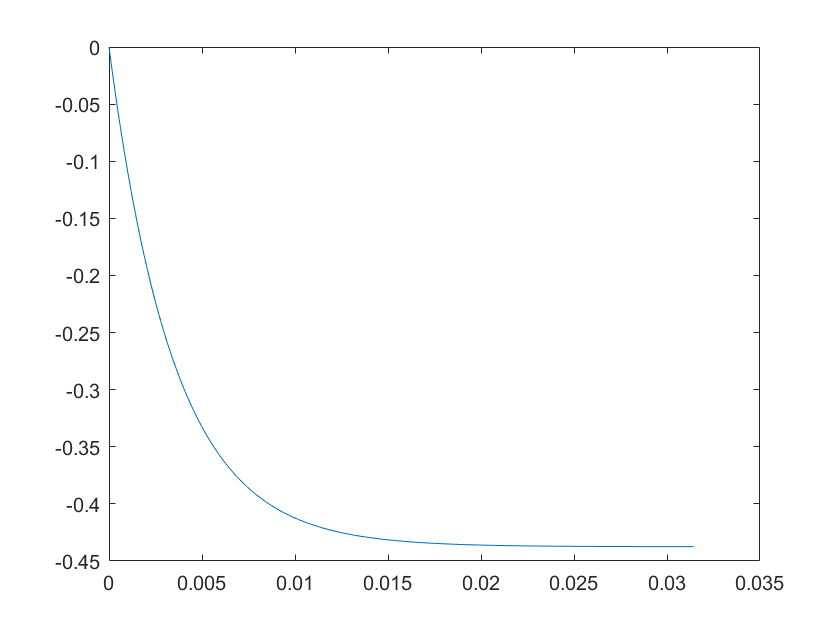

[u,v] = step(H);
plot(v,u)

stepinfo(H)

ans = struct with fields:
        RiseTime: 0.0077
    SettlingTime: 0.0137
     SettlingMin: -0.4375
     SettlingMax: -0.3938
       Overshoot: 0
      Undershoot: 0
            Peak: 0.4375
        PeakTime: 0.0369


## Postlab

### Problem 1

***Discuss the advantages and disadvantages between the Symbolic Math Toolbox and MATLAB alone to convert a transfer function from factored form to polynomial form and vice versa.***

### Problem 2

***In Lab Problem 2 and 3, you analyzed an electrical system and a mechanical system. Do you think there are ways for you to model mechanical systems and electrical systems? If so (and without Google or the textbook), what do you think would be the analogs between the mechanical and electrical world? Take a second and think/write about if you think this is a coincidence. ***

### Problem 3

*Specifically in Lab Problem 4 you looked at what seemed to be a second order system, but it behaved like a first order system. You then changed a parameter until the system began to, well, stop acting like a first order system. For starters, what made you think that it was not acting like a second order system (what features of the response made it seem like it was not a first order system)? *

I realized that the system was no longer behaving like a first order system because as it approached the steady state, the output began to oscillate. 

*Take a look at the poles of the system and discuss what happens to them as the system stops looking like a first order system.*

When it stops looking like a first order system, the poles begin to have a complex component.

### Problem 4

*In Lab Problem 5, you looked at a system that actually had gain. What did you notice about the rise time as you adjusted the gain of the system?*

R_1 had no effect on the rise time but as R_2 increased, the rise time also increased. The higher the value of R_2, the capacitor charged faster as more current went to the capacitor compared to lower values of R_2. R_1 had no effect on rise time since there is a virtual ground between R_1 and the parralel combination between the capcitor and R_2.